%--------------------------------%
%------------ Import ------------%
%--------------------------------%

data5C_1 = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 12.27.24.txt").data(:,2);
data5C_2 = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 16.11.09.txt").data(:,2);
data5C_3 = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 20.05.37.txt").data(:,2);

data10C_1_up = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 12.54.19.txt").data(:,2);
data10C_2_up = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 16.54.32.txt").data(:,2);
data10C_3_up = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 20.34.42.txt").data(:,2);

data25C_1_up = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 13.22.15.txt").data(:,2);
data25C_2_up = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 17.27.51.txt").data(:,2);
data25C_3_up = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 21.02.25.txt").data(:,2);

data40C_1 = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 13.52.30.txt").data(:,2);
data40C_2 = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 17.57.29.txt").data(:,2);
data40C_3 = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 21.34.34.txt").data(:,2);

data25C_1_down = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 14.33.43.txt").data(:,2);
data25C_2_down = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 18.44.05.txt").data(:,2);
data25C_3_down = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 22.33.53.txt").data(:,2);

data10C_1_down = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 15.20.19.txt").data(:,2);
data10C_2_down = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 19.35.12.txt").data(:,2);
data10C_3_down = importdata("Christoffer\P3\3.cyklus\Log Data 18-04-2023 08.48.40.txt").data(:,2);


%--------------------------------%
%-------- Temp Convert ----------%
%--------------------------------%
A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;



eq = @(rs) 1./(A + B*log(rs) + C*log(rs).^(n-1) + D*log(rs).^n) - 273.15;

data5C_1_temp = eq(data5C_1);
data5C_2_temp = eq(data5C_2);
data5C_3_temp = eq(data5C_3);

data10C_1_up_temp = eq(data10C_1_up);
data10C_2_up_temp = eq(data10C_2_up);
data10C_3_up_temp = eq(data10C_3_up);

data25C_1_up_temp = eq(data25C_1_up);
data25C_2_up_temp = eq(data25C_2_up);
data25C_3_up_temp = eq(data25C_3_up);

data40C_1_up_temp = eq(data40C_1);
data40C_2_up_temp = eq(data40C_2);
data40C_3_up_temp = eq(data40C_3);

data25C_1_down_temp = eq(data25C_1_down);
data25C_2_down_temp = eq(data25C_2_down);
data25C_3_down_temp = eq(data25C_3_down);

data10C_1_down_temp = eq(data10C_1_down);
data10C_2_down_temp = eq(data10C_2_down);
data10C_3_down_temp = eq(data10C_3_down);


%--------------------------------%
%------------ STD ---------------%
%--------------------------------%

data5C_1_STD = std(data5C_1_temp)

data5C_1_STD =      0.028455


data5C_2_STD = std(data5C_2_temp)

data5C_2_STD =        0.1043


data5C_3_STD = std(data5C_3_temp)

data5C_3_STD =      0.027519


data5C_STDS = [data5C_1_STD, data5C_2_STD, data5C_3_STD]

data5C_STDS =      0.028455       0.1043     0.027519



data10C_1_up_STD = std(data10C_1_up_temp)

data10C_1_up_STD =      0.024044


data10C_2_up_STD = std(data10C_2_up_temp)

data10C_2_up_STD =      0.020933


data10C_3_up_STD = std(data10C_3_up_temp)

data10C_3_up_STD =      0.017711


data10C_up_STDS = [data10C_1_up_STD, data10C_2_up_STD, data10C_3_up_STD]

data10C_up_STDS =      0.024044     0.020933     0.017711




data25C_1_up_STD = std(data25C_1_up_temp)

data25C_1_up_STD =      0.018449


data25C_2_up_STD = std(data25C_2_up_temp)

data25C_2_up_STD =      0.019017


data25C_3_up_STD = std(data25C_3_up_temp)

data25C_3_up_STD =       0.01458


data25C_up_STDS = [data25C_1_up_STD, data25C_2_up_STD, data25C_3_up_STD]

data25C_up_STDS =      0.018449     0.019017      0.01458



data40C_1_STD = std(data40C_1_up_temp)

data40C_1_STD =      0.014567


data40C_2_STD = std(data40C_2_up_temp)

data40C_2_STD =      0.010699


data40C_3_STD = std(data40C_3_up_temp)

data40C_3_STD =      0.017639


data40C_STDS = [data40C_1_STD, data40C_2_STD, data40C_3_STD]

data40C_STDS =      0.014567     0.010699     0.017639



data25C_1_down_STD = std(data25C_1_down_temp)

data25C_1_down_STD =      0.016662


data25C_2_down_STD = std(data25C_2_down_temp)

data25C_2_down_STD =      0.016584


data25C_3_down_STD = std(data25C_3_down_temp)

data25C_3_down_STD =      0.017942


data25C_down_STDS = [data25C_1_down_STD, data25C_2_down_STD, data25C_3_down_STD]

data25C_down_STDS =      0.016662     0.016584     0.017942



data10C_1_down_STD = std(data10C_1_down_temp)

data10C_1_down_STD =      0.020724


data10C_2_down_STD = std(data10C_2_down_temp)

data10C_2_down_STD =      0.019449


data10C_3_down_STD = std(data10C_3_down_temp)

data10C_3_down_STD =       0.01647


data10C_down_STDS = [data10C_1_down_STD, data10C_2_down_STD, data10C_3_down_STD]

data10C_down_STDS =      0.020724     0.019449      0.01647




%--------------------------------%
%-------- Vores system ----------%
%--------------------------------%

k = 2;

std_5C_STD = std(data5C_STDS)

std_5C_STD =      0.044059


std_10C_STD_up = std(data10C_up_STDS)

std_10C_STD_up =     0.0031667


std_25C_STD_up = std(data25C_up_STDS)

std_25C_STD_up =     0.0024145


std_40C_STD = std(data40C_STDS)

std_40C_STD =     0.0034773


std_25C_STD_down = std(data25C_down_STDS)

std_25C_STD_down =    0.00076286


std_10C_STD_down = std(data10C_down_STDS)

std_10C_STD_down =     0.0021833



STD_STD_ARR = [std_5C_STD, std_10C_STD_up, std_25C_STD_up, std_40C_STD, std_25C_STD_down, std_10C_STD_down];

STD_STD_95A_AVFG = STD_STD_ARR * k %k faktor ganges på for at få 95% intervallet 

STD_STD_95A_AVFG =      0.088118    0.0063334    0.0048291    0.0069545    0.0015257    0.0043665



%--------------------------------%
%---------- Chat GPT ------------%
%--------------------------------%

mean_5C = mean(data5C_STDS)

mean_5C =      0.053423


mean_10C_up = mean(data10C_up_STDS)

mean_10C_up =      0.020896


mean_25C_up = mean(data25C_up_STDS)

mean_25C_up =      0.017349


mean_40C = mean(data40C_STDS)

mean_40C =      0.014302


mean_25C_down = mean(data25C_down_STDS)

mean_25C_down =      0.017063


mean_10C_down = mean(data10C_down_STDS)

mean_10C_down =      0.018881


mean_ARR = [mean_5C, mean_10C_up, mean_25C_up, mean_40C, mean_25C_down, mean_10C_down];


varNames = ["STD af STD", "STD af STD 95%", "Mean af STD"]

varNames = 1×3 string array
    "STD af STD"    "STD af STD 95%"    "Mean af STD"


table(STD_STD_ARR', STD_STD_95A_AVFG', mean_ARR')

ans = 6×3 table
       Var1         Var2         Var3  
    __________    _________    ________

      0.044059     0.088118    0.053423
     0.0031667    0.0063334    0.020896
     0.0024145    0.0048291    0.017349
     0.0034773    0.0069545    0.014302
    0.00076286    0.0015257    0.017063
     0.0021833    0.0043665    0.018881





%--------------------------------%
%------ Faktisk udregning -------%
%--------------------------------%

data5C_1_mean = mean(data5C_1_temp)

data5C_1_mean =       -3.7992


data5C_2_mean = mean(data5C_2_temp)

data5C_2_mean =       -3.6701


data5C_3_mean = mean(data5C_3_temp)

data5C_3_mean =       -3.8237




data5C_mean = [data5C_1_mean, data5C_2_mean, data5C_3_mean]

data5C_mean =       -3.7992      -3.6701      -3.8237


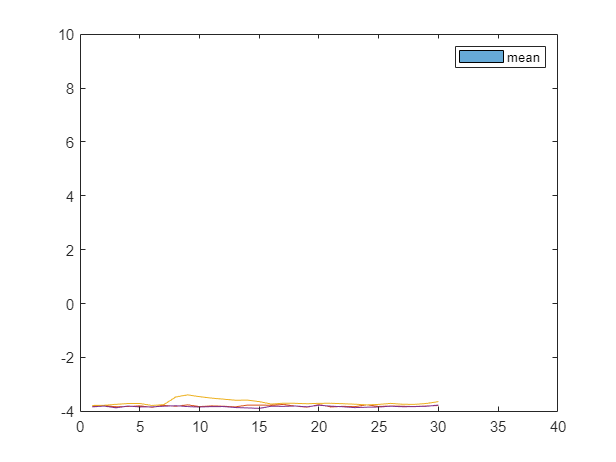


hold ON
plot(data5C_1_temp)
plot(data5C_2_temp)
plot(data5C_3_temp)
hold OFF
legend("mean")
xlim([0, 40])

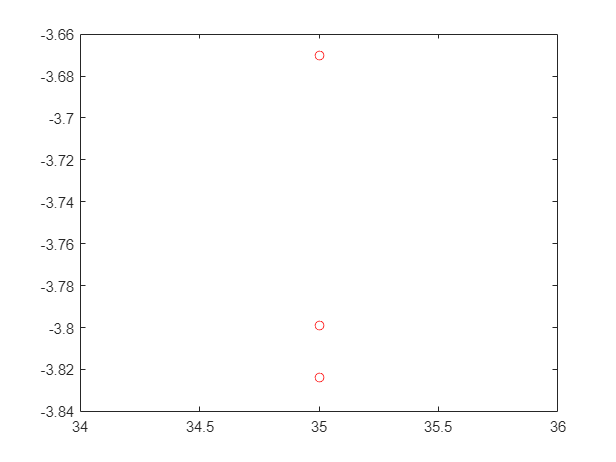


plot(35, data5C_mean, "o", Color="red")


data10C_1_up_mean = mean(data10C_1_up_temp)

data10C_1_up_mean =        11.075


data10C_2_up_mean = mean(data10C_2_up_temp)

data10C_2_up_mean =        11.043


data10C_3_up_mean = mean(data10C_3_up_temp)

data10C_3_up_mean =        10.996


data10C_mean_up = [data10C_1_up_mean, data10C_2_up_mean, data10C_3_up_mean]

data10C_mean_up =        11.075       11.043       10.996



data25C_1_up_mean = mean(data25C_1_up_temp)

data25C_1_up_mean =        25.738


data25C_2_up_mean = mean(data25C_2_up_temp)

data25C_2_up_mean =        25.712


data25C_3_up_mean = mean(data25C_3_up_temp)

data25C_3_up_mean =        25.716


data25C_mean_up = [data25C_1_up_mean, data25C_2_up_mean, data25C_3_up_mean]

data25C_mean_up =        25.738       25.712       25.716



data40C_1_mean = mean(data40C_1_up_temp)

data40C_1_mean =        40.326


data40C_2_mean = mean(data40C_2_up_temp)

data40C_2_mean =        40.322


data40C_3_mean = mean(data40C_3_up_temp)

data40C_3_mean =        40.345


data40C_mean = [data40C_1_mean, data40C_2_mean, data40C_3_mean]

data40C_mean =        40.326       40.322       40.345



data25C_1_down_mean = mean(data25C_1_down_temp)

data25C_1_down_mean =        25.776


data25C_2_down_mean = mean(data25C_2_down_temp)

data25C_2_down_mean =        25.728


data25C_3_down_mean = mean(data25C_3_down_temp)

data25C_3_down_mean =        25.772


data25C_mean_down = [data25C_1_down_mean, data25C_2_down_mean, data25C_3_down_mean]

data25C_mean_down =        25.776       25.728       25.772




data10C_1_down_mean = mean(data10C_1_down_temp)

data10C_1_down_mean =        11.113


data10C_2_down_mean = mean(data10C_2_down_temp)

data10C_2_down_mean =        11.038


data10C_3_down_mean = mean(data10C_3_down_temp)

data10C_3_down_mean =        11.123


data10C_mean_down = [data10C_1_down_mean, data10C_2_down_mean, data10C_3_down_mean]

data10C_mean_down =        11.113       11.038       11.123



data5c_std = std(data5C_mean)

data5c_std =      0.082513


data10c_up_std = std(data10C_mean_up)

data10c_up_std =      0.039796


data25c_up_std = std(data25C_mean_up)

data25c_up_std =      0.014275


data40c_std = std(data40C_mean)

data40c_std =      0.012475


data25c_down_std = std(data25C_mean_down)

data25c_down_std =       0.02623


data10c_down_std = std(data10C_mean_down)

data10c_down_std =      0.046312
